clear all;
addpath("Monopole-dipole/");
multiplier = 2;
lambda0=1;%um
lambdaFinal = 1000000;%um
len = floor(log(lambdaFinal/lambda0)/log(multiplier))+1;
zMin = [3];%um
mass_length=20;%um
mass_span=2; %um; Along k vector;

atoms_length=5; %um; Atom along k vector
atoms_width=2; %um; Beam waist*2
sample=50;

geo=zeros(length(zMin),len,sample);
for j=1:length(zMin)
    for k=1:len
        lambda(k) = lambda0*multiplier^(k-1);
        sum=0;
        for i=1:sample
            x0=randn*atoms_length/2;
            y0=randn*atoms_width/2;
            z0=randn*atoms_width/2;
            geo(j,k,i)=geofactor(lambda(k),zMin(j),x0,y0,z0,mass_length,mass_span);
        end    
        k
    end
end

k = 1

k = 2

k = 3

k = 4

k = 5

k = 6

k = 7

k = 8

k = 9

k = 10

k = 11

k = 12

k = 13

k = 14

k = 15

k = 16

k = 17

k = 18

k = 19

k = 20

g_factor=mean(geo,3);
g_error=std(geo,0,3)./sqrt(sample-1);
g_factor=g_factor*10^(-6);
g_error=g_error*10^(-6);

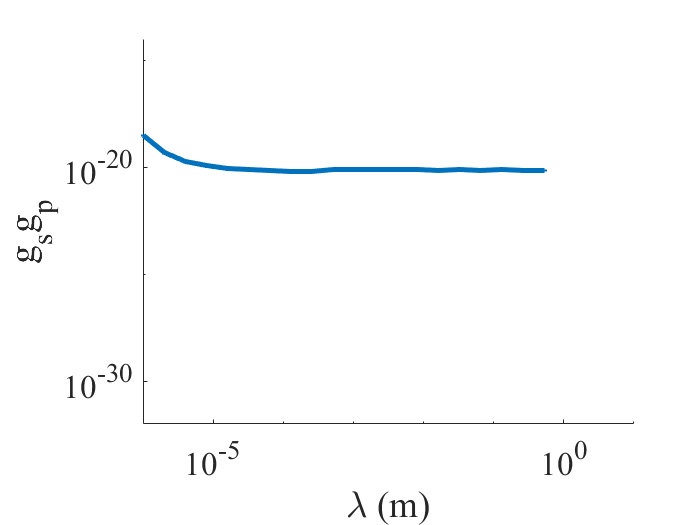

deltaX=0.1/sqrt(1000)./sqrt(333);
hbar=Constant.ReducedPlanck;
Na=Constant.AvogadroNumber;
mn=Constant.AtomicMass;
rho_pt=21.45; % g/cm^3
n=rho_pt/1000/mn*10^6; % /m^3
omega1=2*pi*10;
omega2=2*pi*7;
c1=0.3;
c2=0.3;

figure;
hold on
for i=1:length(zMin)
gsgp(:)=deltaX./(hbar*n*(c1*omega2-c2*omega1)./(8*pi*mn*omega2).*g_factor(i,:));
gsgp_error(:)=deltaX./(hbar*n*(c1*omega2-c2*omega1)./(8*pi*mn*omega2).*g_factor(i,:).^2).*g_error(i,:);
l=errorbar(lambda.*10^(-6),abs(gsgp),abs(gsgp_error),'CapSize',0);
set(l,'linewidth',3)
end
set(gca,'XScale','log','YScale','log','fontsize',20)
set(gca,'fontname','times new roman')
xlabel('\lambda (m)')
ylabel('g_sg_p')
ylim([1e-32 1e-14])
xlim([1e-6 1e1])

function output = geofactor(lambda,zMin,x0,y0,z0,mass_length,mass_span)
    fun = @(x,y,z) (1./(distance(x,y,z,x0,y0,z0).*lambda) + 1./distance(x,y,z,x0,y0,z0).^2).*...
    exp(-distance(x,y,z,x0,y0,z0)./lambda).*z./distance(x,y,z,x0,y0,z0);
    output = integral3(fun,-mass_span/2,mass_span/2,-mass_length/2,mass_length/2,zMin,zMin+mass_length);
end

function output = distance(x1,y1,z1,x2,y2,z2)
    output = sqrt((x1-x2).^2+(y1-y2).^2+(z1-z2).^2);
end